# Inizializzazione

close all
clc
clear

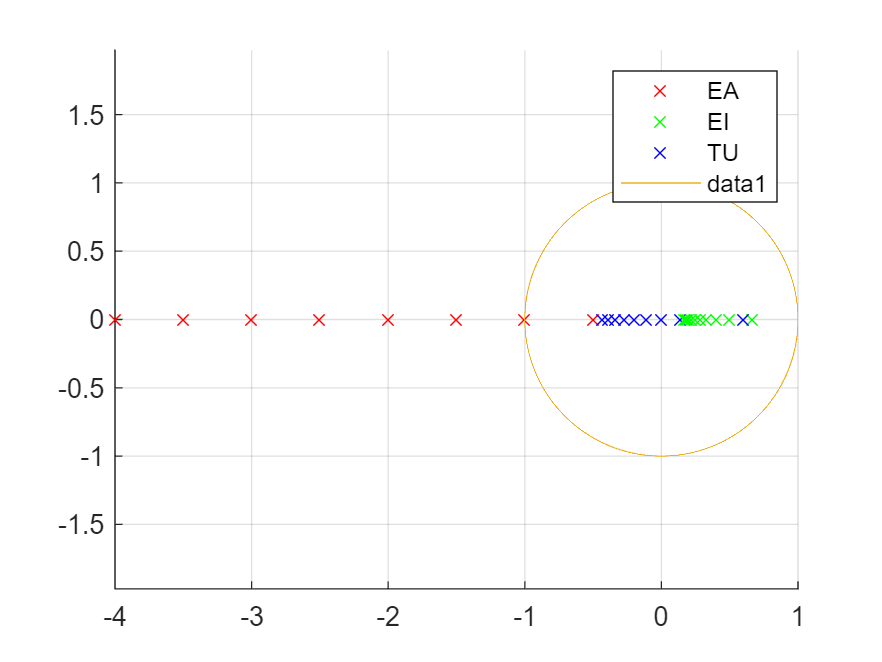

tau = 0.2;
Ts = 0.1:0.1:1;
s = tf('s');
R = s / (tau * s + 1);

figure
hold on; grid on; axis equal;

for i = 1:length(Ts)
    Ti = Ts(i);
    z = tf('z', Ti);
    sa = (z - 1) / Ti;
    Ra = minreal(sa / (tau * sa + 1));
    si = (1 - z^-1) / Ti;
    Ri = minreal(si / (tau * si + 1));
    Rt = c2d(R, Ti, "tustin");

    plot(real(pole(Ra)), imag(pole(Ra)), "rx")
    plot(real(pole(Ri)), imag(pole(Ri)), "gx")
    plot(real(pole(Rt)), imag(pole(Rt)), "bx")
end
legend('EA', 'EI', 'TU');
th = 0:0.001:2*pi;
plot(cos(th), sin(th))

Eulero all'indietro e Tustin mantengono la stabilità del sistema per ogni T, mentre Eulero in avanti la mantiene solo per T < 0.2s

Studio solo le discretizzazioni di Eulero all'indietro e Tustin, in quanto sono le uniche BIBO stabili.

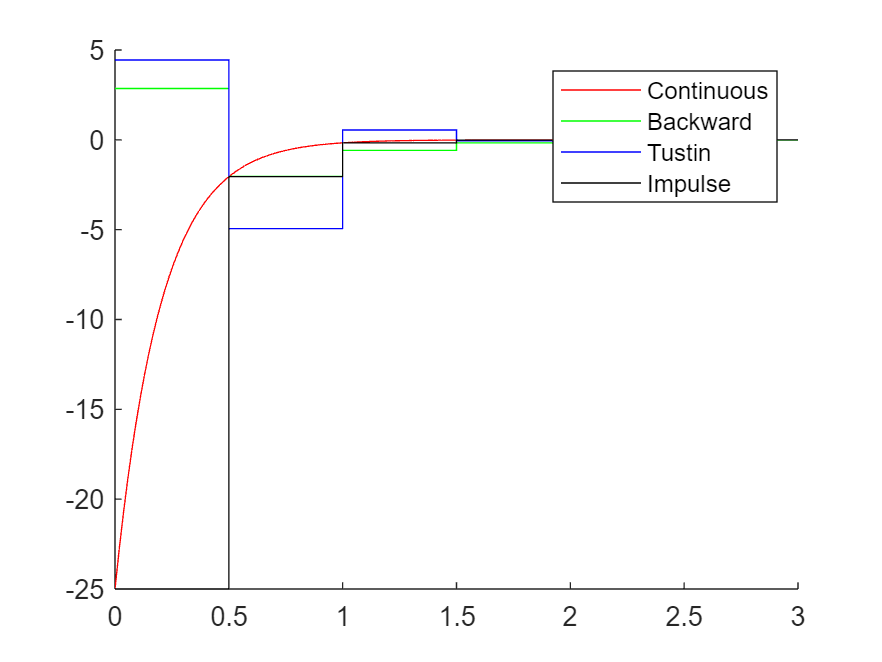

T = 0.5;
z = tf('z', T);
si = (1 - z^-1) / T;
Ri = minreal(si / (tau * si + 1));
Rt = c2d(R, T, "tustin");
Rr = c2d(R, T, "impulse");

Tfinal = 3;
[yR, t] = impulse(R, Tfinal);
[yRi, ti] = impulse(Ri, Tfinal);
[yRt, tt] = impulse(Rt, Tfinal);
[yRr, tr] = impulse(Rr, Tfinal);

figure
hold on
plot(t, yR, "r")
stairs(ti, yRi, "g")
stairs(tt, yRt, "b")
stairs(tr, yRr, "k")
legend("Continuous", "Backward", "Tustin", "Impulse")

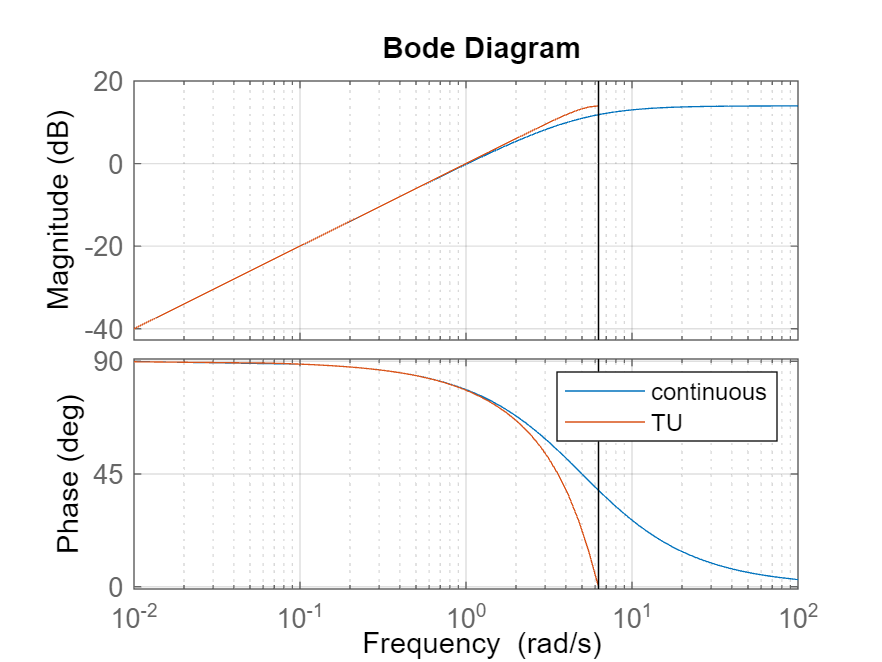

figure
bode(R, Rt)
grid on
legend('continuous', 'TU')

wN = pi / T;
wbar = wN / 2;

[Mc,Pc] = bode(R,wbar);
[MdTU,PdTU] = bode(Rt,wbar);

deltaM = 20*log10(MdTU)-20*log10(Mc)

deltaM = 1.3948

deltaP = PdTU-Pc

deltaP = -6.5179

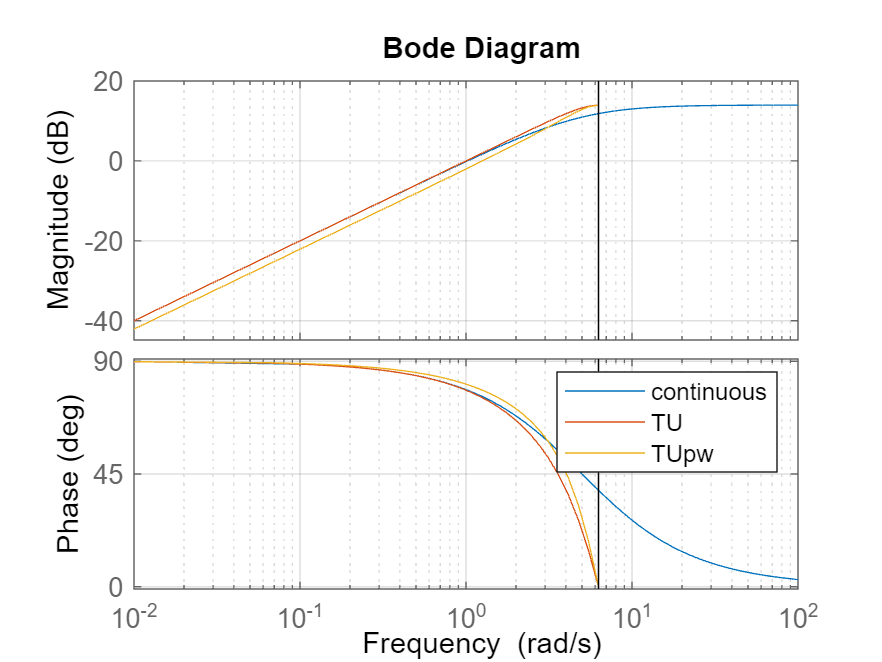

opt = c2dOptions('Method', 'Tustin', 'PrewarpFrequency', wbar);
Rtw = c2d(R, T, opt);

figure
bode(R, Rt, Rtw)
grid on
legend('continuous', 'TU', 'TUpw');

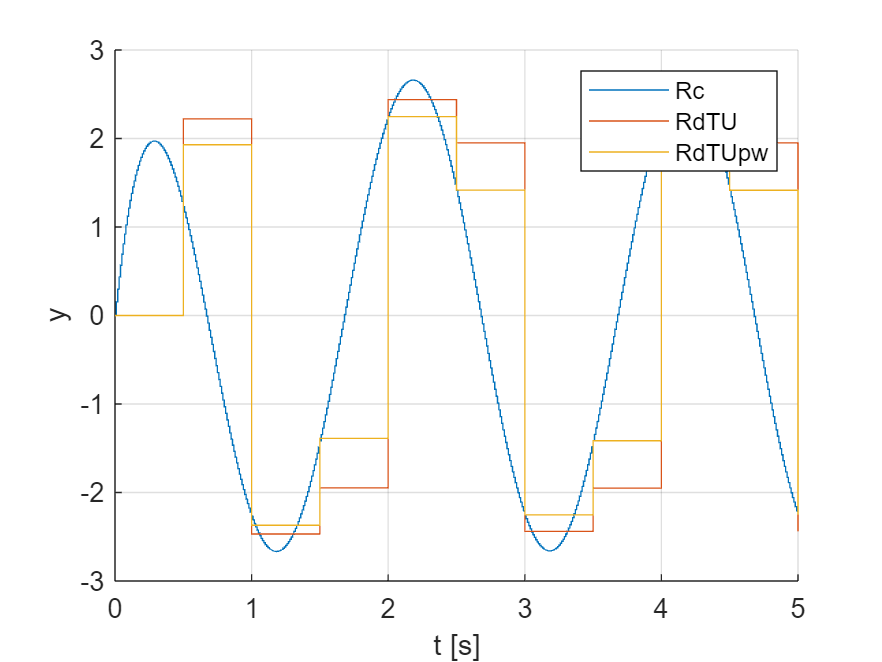

ts = 0:0.01:5;
sints = sin(wbar * ts);
yR = lsim(R, sints, ts);
td = 0:T:5;
sintd = sin(wbar * td);
yRt = lsim(Rt, sintd, td);
yRtw = lsim(Rtw, sintd, td);

figure
hold on; grid on;
xlabel('t [s]'); ylabel('y');
stairs(ts,yR)
stairs(td,yRt)
stairs(td,yRtw)
legend('Rc', 'RdTU', 'RdTUpw')

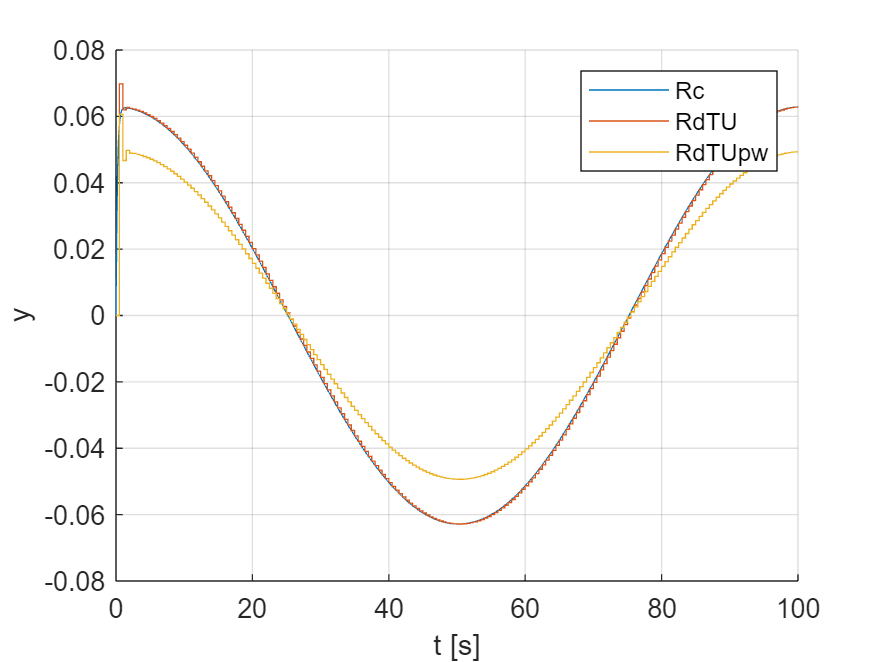

wl = wN/100;
tc = 0:.01:100;
u = sin(wl*tc);
yRc = lsim(R,u,tc);
t = 0:T:100;
u = sin(wl*t);
yRdTU = lsim(Rt,u,t);
yRdTUpw = lsim(Rtw,u,t);

figure
hold on; grid on;
xlabel('t [s]'); ylabel('y');
stairs(tc,yRc)
stairs(t,yRdTU)
stairs(t,yRdTUpw)
legend('Rc', 'RdTU', 'RdTUpw')